For $c=1$ we get the eigenvalues:

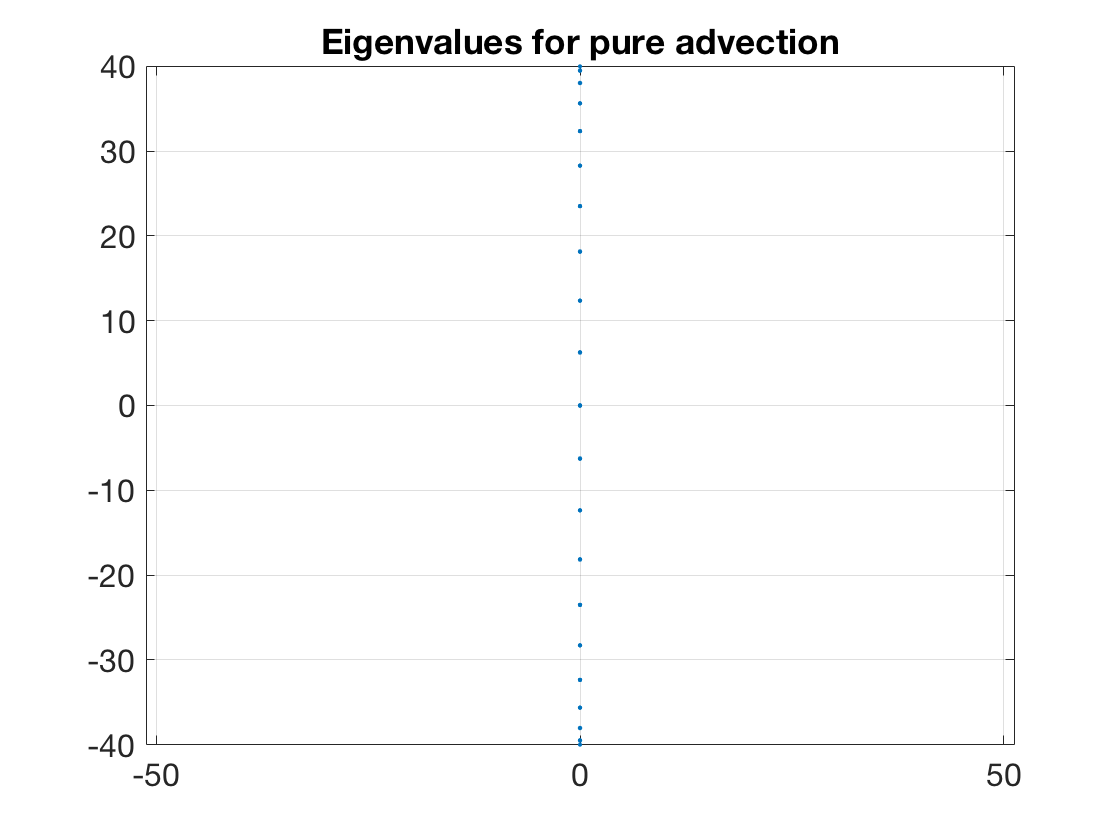

[x,Dx] = diffper(40,[0,1]);
lambda = eig(Dx);
plot(real(lambda),imag(lambda),'.')
axis equal, grid on    % ignore this line
title('Eigenvalues for pure advection')    % ignore this line

Let's choose a time step of $\tau=0.1$ and compare to the stability regions of the Euler and backward Euler time steppers.

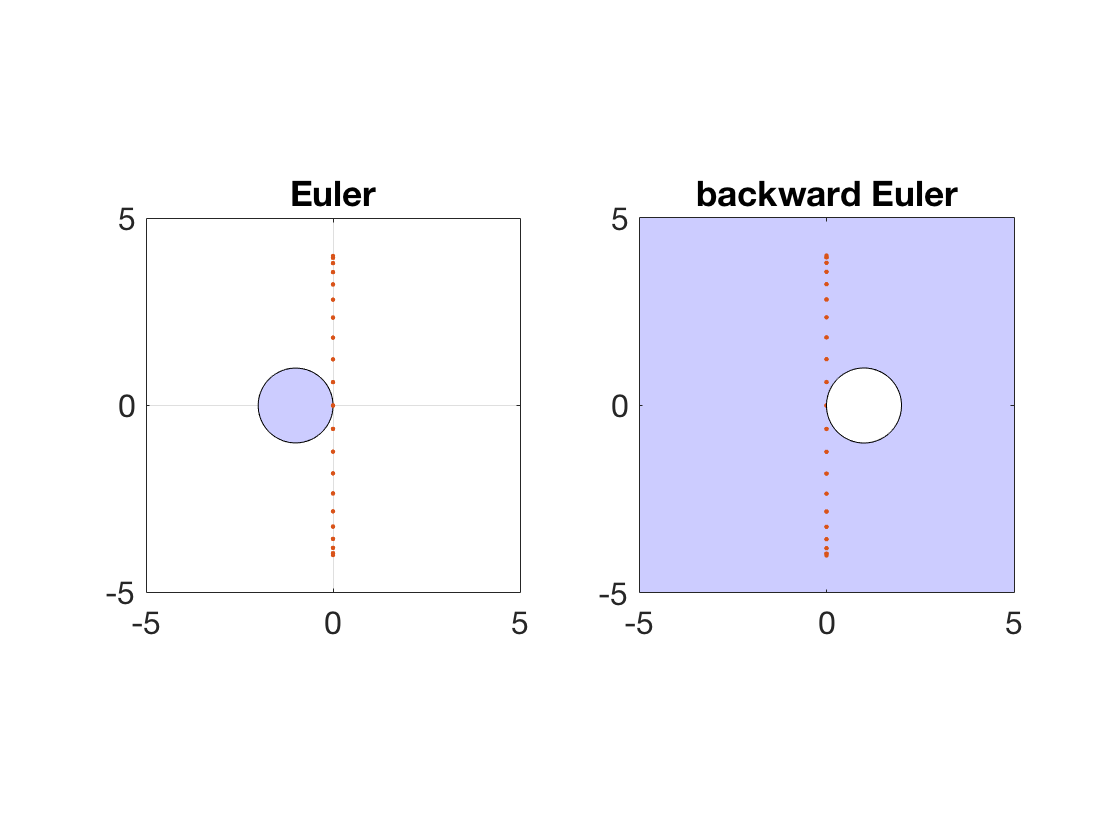

zc = exp(1i*linspace(0,2*pi,361)');    % points on |z|=1

subplot(1,2,1)
z = zc - 1;                            % shift left by 1
fill(real(z),imag(z),[.8 .8 1])
hold on, plot(real(0.1*lambda),imag(0.1*lambda),'.')
axis equal, axis square, axis([-5 5 -5 5]), grid on    % ignore this line
title('Euler')    % ignore this line

subplot(1,2,2)
fill([-6 6 6 -6],[-6 -6 6 6],[.8 .8 1])
z = zc + 1;                            % shift right by 1
hold on, plot(real(0.1*lambda),imag(0.1*lambda),'.')
fill(real(z),imag(z),'w')
axis equal, axis square, axis([-5 5 -5 5]), grid on    % ignore this line
title('backward Euler')    % ignore this line

In the Euler case it's clear that *no* real value of $\tau>0$ is going to make all (or even any) of the $\tau\lambda_j$ fit within the stability region. Hence Euler will never produce bounded solutions to this discretization of the advection equation. The A-stable backward Euler time stepping tells the exact opposite story; it will be absolutely stable regardless of $\tau$.